# PRACTICA 8 Algunas t´ecnicas de procesado de im´agenes con wavelets

## Ejercicio 1: Detecci´on de contornos 

#### - Crear un c´odigo en el Live Script que tome como input una imagen en escala de grises, y de como resultado una imagen binaria que muestre los contornos de la imagen inicial. Seguir el proceso descrito en esta presentaci´on usando la transformada wavelet de nivel 1. 

#### - Usar como im´agenes de prueba rice.tif, peppers.tif, lena gr.tif. Ajustar el umbral que mejor resultados produzca. 

#### - Experimentar con distintos tipos de wavelets, observando cu´ales funcionan mejor. 

#### - Comparar el resultado con otros detectores de bordes, por ejemplo: BW1 = edge(I,’sobel’); BW2 = edge(I,’canny’); imshow(BW1) figure, imshow(BW2)

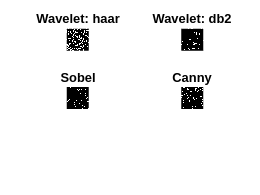

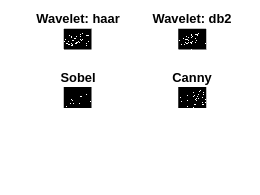

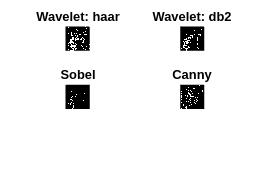

% Cargar imágenes
rice = imread('rice.tif');
peppers = imread('peppers.png'); % Usar la extensión png ya que 'peppers.tif' podría no estar disponible
lena = imread('lena_gr.tif');

% Convertir imágenes a escala de grises si no lo están
if size(peppers, 3) == 3
    peppers = rgb2gray(peppers);
end
if size(lena, 3) == 3
    lena = rgb2gray(lena);
end

% Lista de imágenes
imagenes = {rice, peppers, lena};
nombres_imagenes = {'Rice', 'Peppers', 'Lena'};

% Lista de wavelets a probar
wavelets = {'haar', 'db2'};

% Umbral para binarización
umbral = 10;

for i = 1:length(imagenes)
    I = imagenes{i};
    
    figure('Name', nombres_imagenes{i});
    
    for j = 1:length(wavelets)
        wavelet = wavelets{j};
        
        % Realizar descomposición wavelet de nivel 1
        [C, S] = wavedec2(I, 1, wavelet);
        
        % Extraer coeficientes de detalle horizontal, vertical y diagonal
        H1 = wrcoef2('h', C, S, wavelet, 1);
        V1 = wrcoef2('v', C, S, wavelet, 1);
        D1 = wrcoef2('d', C, S, wavelet, 1);
        
        % Calcular la suma absoluta de los coeficientes de detalle
        DET = abs(H1) + abs(V1) + abs(D1);
        
        % Binarizar la matriz DET con el umbral dado
        CONTORNOS = DET > umbral;
        
        subplot(3, length(wavelets), j);
        imshow(CONTORNOS);
        title(['Wavelet: ', wavelet]);
    end
    
    % Detección de bordes usando Sobel y Canny
    BW1 = edge(I, 'sobel');
    BW2 = edge(I, 'canny');
    
    subplot(3, length(wavelets), length(wavelets) + 1);
    imshow(BW1);
    title('Sobel');
    
    subplot(3, length(wavelets), length(wavelets) + 2);
    imshow(BW2);
    title('Canny');
end

## Ejercicio 3: Realce de detalles 

#### - Escribir un script que tome como input una imagen, que la convierta a escala de grises, y de como resultado una versi´on de la imagen original con los bordes realzados. 

#### - Para ello seguir el proceso descrito en esta presentaci´on a partir de la transformada wavelet de nivel 1. 

#### - Pod´eis usar como im´agenes de prueba house gr.tiff y boat512.tiff. 

#### - Comparar el efecto de diferentes tipos de wavelets. 

#### - Modificar el algoritmo utilizando las transformadas de nivel 1 y 2 y aplicando un factor diferente a las fluctuaciones de niveles 1 y 2, o cualquier otra idea.

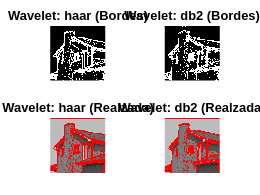

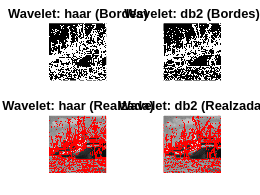

% Cargar imágenes de prueba
house = imread('house_gr.tiff');
boat = imread('boat512.tiff');

% Convertir imágenes a escala de grises si no lo están
if size(house, 3) == 3
    house = rgb2gray(house);
end
if size(boat, 3) == 3
    boat = rgb2gray(boat);
end

% Lista de imágenes
imagenes = {house, boat};
nombres_imagenes = {'House', 'Boat'};

% Lista de wavelets a probar
wavelets = {'haar', 'db2'};

% Umbral para binarización
umbral = 10;

% Factores para fluctuaciones de niveles 1 y 2
factor_nivel_1 = 1.0;
factor_nivel_2 = 0.5;

for i = 1:length(imagenes)
    I = imagenes{i};
    
    figure('Name', nombres_imagenes{i});
    
    for j = 1:length(wavelets)
        wavelet = wavelets{j};
        
        % Realizar descomposición wavelet de nivel 1
        [C, S] = wavedec2(I, 1, wavelet);
        
        % Extraer coeficientes de detalle horizontal, vertical y diagonal de nivel 1
        H1 = wrcoef2('h', C, S, wavelet, 1);
        V1 = wrcoef2('v', C, S, wavelet, 1);
        D1 = wrcoef2('d', C, S, wavelet, 1);
        
        % Calcular la suma absoluta de los coeficientes de detalle de nivel 1
        DET1 = abs(H1) + abs(V1) + abs(D1);
        
        % Realizar descomposición wavelet de nivel 2
        [C, S] = wavedec2(I, 2, wavelet);
        
        % Extraer coeficientes de detalle horizontal, vertical y diagonal de nivel 2
        H2 = wrcoef2('h', C, S, wavelet, 2);
        V2 = wrcoef2('v', C, S, wavelet, 2);
        D2 = wrcoef2('d', C, S, wavelet, 2);
        
        % Calcular la suma absoluta de los coeficientes de detalle de nivel 2
        DET2 = abs(H2) + abs(V2) + abs(D2);
        
        % Aplicar factores a las fluctuaciones de niveles 1 y 2
        DET = factor_nivel_1 * DET1 + factor_nivel_2 * DET2;
        
        % Binarizar la matriz DET con el umbral dado
        CONTORNOS = DET > umbral;
        
        % Realzar bordes en la imagen original
        I_realzada = imoverlay(I, CONTORNOS, [1 0 0]);
        
        subplot(2, length(wavelets), j);
        imshow(CONTORNOS);
        title(['Wavelet: ', wavelet, ' (Bordes)']);
        
        subplot(2, length(wavelets), length(wavelets) + j);
        imshow(I_realzada);
        title(['Wavelet: ', wavelet, ' (Realzada)']);
    end
end

## Ejercicio 4: Hacer zoom en una imagen

#### Escribir un script que tome como input una imagen, que la convierta a escala de grises, y de como resultado una versi´on (con un n´umero de p´ıxeles mayor que la imagen original. Para ello: 

#### - Tomar la imagen original como si fuera la subimagen de detalle de nivel 1 (cA1), consideremos los detalles cH1, cV1 y cD1 igual a cero y reconstruir. 

#### - Guardar dicha imagen en formato imagen con imwrite, puuede ser necesario usar previamente imadjust. 

#### - Hacer zoom en la imagen original y en la nueva para combrobar si disminuye el efecto de pixelado. Representar los resultados. 

#### - El proceso se puede repetir dos o tres veces mas o, equivalentemente, tomar la imagen inicial como cA2 o cA3, con todos los coeficientes de detalle nulos y reconstruir.

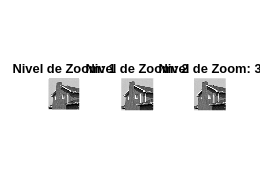

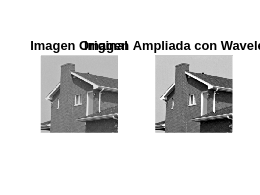

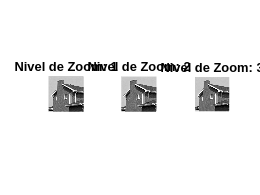

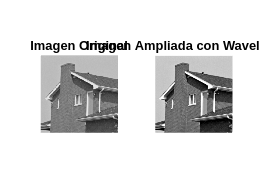

clear
% Cargar la imagen de prueba
I = imread('house_gr.tiff');

% Convertir la imagen a escala de grises si no lo está
if size(I, 3) == 3
    I = rgb2gray(I);
end

% Normalizar la imagen
I = im2double(I);

% Lista de wavelets a probar
wavelets = {'haar', 'db2'};

% Número de niveles de aumento
niveles = 3;

for j = 1:length(wavelets)
    wavelet = wavelets{j};
    I_zoom = I;
    
    figure('Name', ['Wavelet: ', wavelet]);
    
    for k = 1:niveles
        % Reconstruir utilizando la transformada inversa con coeficientes de detalle nulos
        I_zoom = idwt2(I_zoom, [], [], [], wavelet);
        
        % Ajustar la imagen para mejor visualización
        I_zoom = imadjust(I_zoom);
        
        % Mostrar la imagen ampliada
        subplot(1, niveles, k);
        imshow(I_zoom);
        title(['Nivel de Zoom: ', num2str(k)]);
    end
    
    % Guardar la imagen final
    nombre_archivo = ['Imagen_zoom_', wavelet, '_nivel_', num2str(niveles), '.png'];
    imwrite(I_zoom, nombre_archivo);
    
    % Mostrar comparación de zoom entre la imagen original y la ampliada
    figure('Name', ['Comparación de Zoom: ', wavelet]);
    subplot(1, 2, 1);
    imshow(I);
    title('Imagen Original');
    
    subplot(1, 2, 2);
    imshow(I_zoom);
    title(['Imagen Ampliada con Wavelet: ', wavelet]);
end

## Ejercicio 5: Fusi´on de im´agenes En el Live Script crear un c´odigo para: 

#### - Cargar dos im´agenes, Fusion imagen1.jpg y Fusion imagen2.jpg, 

#### - Fusionarlas utilizando la orden wfusimg produzca como resultado una imagen que est´e enfocada tanto el fondo como el primer plano. 

#### - Representar las im´agenes originales junto con la fusionada. Experimentar modificando la wavelet y el nivel de descomposici´on. 

#### - Experimentar modificando el m´etodo de fusi´on de las aproximaciones y de los detalles.

%% Fusionar Imágenes con Wavelet

% Cargar imágenes
imagen1 = imread('Fusion_imagen_1.jpg');
imagen2 = imread('Fusion_imagen_2.jpg');

% Convertir imágenes a escala de grises si no lo están
if size(imagen1, 3) == 3
    imagen1 = rgb2gray(imagen1);
end
if size(imagen2, 3) == 3
    imagen2 = rgb2gray(imagen2);
end

% Mostrar imágenes originales
figure;
subplot(1, 3, 1);
imshow(imagen1);
title('Imagen 1');

subplot(1, 3, 2);
imshow(imagen2);
title('Imagen 2');

%% Fusionar las imágenes
wavelets = {'haar', 'db2', 'sym4', 'coif1'};
niveles = [1, 2, 3];
metodos_aprox = {'mean', 'max', 'min'};
metodos_detalle = {'mean', 'max', 'min'};

for w = 1:length(wavelets)
    for n = 1:length(niveles)
        for ma = 1:length(metodos_aprox)
            for md = 1:length(metodos_detalle)
                wavelet = wavelets{w};
                nivel = niveles(n); % Corregido para indexar arreglo numérico
                metodo_aprox = metodos_aprox{ma};
                metodo_detalle = metodos_detalle{md};

                % Fusionar imágenes utilizando wfusimg
                imagen_fusionada = wfusimg(imagen1, imagen2, wavelet, nivel, metodo_aprox, metodo_detalle);

                % Mostrar imagen fusionada
                figure;
                subplot(1, 3, 1);
                imshow(imagen1);
                title('Imagen 1');

                subplot(1, 3, 2);
                imshow(imagen2);
                title('Imagen 2');

                subplot(1, 3, 3);
                imshow(imagen_fusionada);
                title(['Fusionada: ', wavelet, ', Nivel: ', num2str(nivel), ', Aproximación: ', metodo_aprox, ', Detalle: ', metodo_detalle]);
                
                % Guardar imagen fusionada
                nombre_archivo = ['Fusionada_', wavelet, '_nivel_', num2str(nivel), '_aprox_', metodo_aprox, '_detalle_', metodo_detalle, '.png'];
                imwrite(imagen_fusionada, nombre_archivo);
            end
        end
    end
end


# FUNCIONES

function J = imoverlay(I, mask, color)
    % Función para realzar bordes en la imagen original
    if size(I, 3) == 1
        I = repmat(I, [1 1 3]);
    end
    J = I;
    for k = 1:3
        J(:,:,k) = I(:,:,k) .* uint8(~mask) + uint8(color(k) * 255) .* uint8(mask);
    end
end